Задание:

Доказать сходимость, найти область сходимости функции и вычислить значение на отрезке [0, 5] с шагом 0,5 с заданной точностью.

V(x) = $\int_0^x \frac{\left(\cos \;t-1\right)\mathrm{dt}}{t}$

Ряд Тейлора:

V(x) = $\sum_{n=1}^{\infty } \frac{{\left(-1\right)}^n x^{2n} }{2n\left(2n\right)!}$

Это знакопеременный ряд $\sum_{n=1}^{\infty } {\left(-1\right)}^n с$, где $u_n$$\ge$ 0. Так как x ограничен, то $\frac{x^{2n+2} }{\left(2n+2\right)\left(2n+2\right)!}$ * $\frac{2n\left(2n\right)!}{x^{2n} }$ =$\frac{nx^2 }{\left(n+1\right)\left(2n+1\right)\left(2n+2\right)}$ $\to 0$ при $n$$\to \infty$. Следовательно, $u_{i+1}$< $u_i$ $\forall i\in N\ldotp$

$\lim_{n\to \infty } \frac{x^{2n} }{2n\left(2n\right)!}$=$\frac{1}{2}$ $\lim_{n\to \infty } \frac{x^{2n} }{n\left(2n\right)!}$ = (т.к. x фиксированная, то факториал возрастает быстрее, чем степенная функция) = 0

Следовательно,  $\sum_{n=1}^{\infty } \frac{{\left(-1\right)}^n x^{2n} }{2n\left(2n\right)!}$ - ряд Лейбница. $\Rightarrow$Он сходится на x$\in$[0, 5].

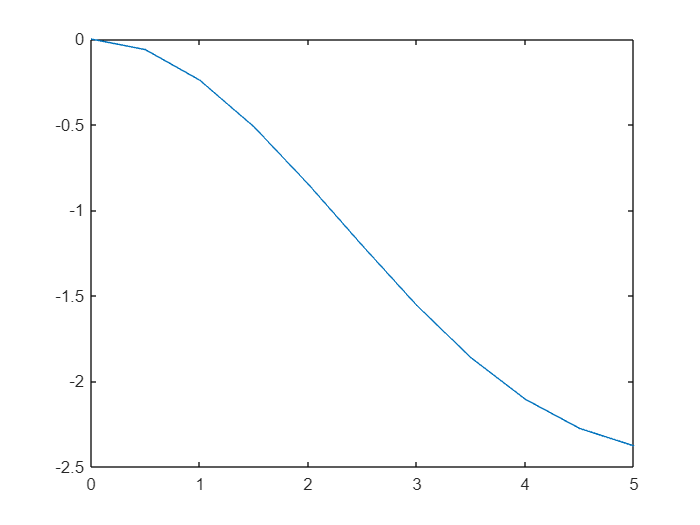

close all
clear all
clc
x = 0:0.5:5;
e = 1e-15;
[y, ki] = intcos(x, e);

figure('Name','V(x)');
plot(x, y);

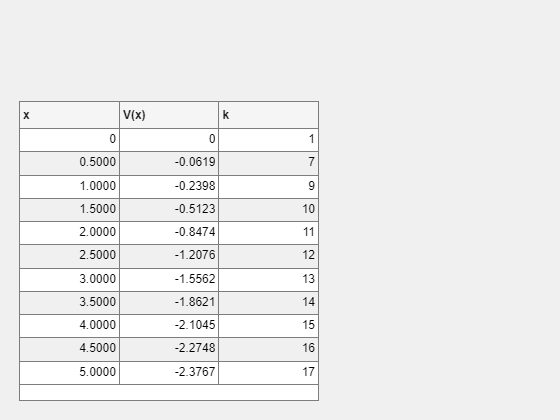

VxT = table(x',y',ki','VariableNames',{'x','V(x)','k'});
fig = uifigure('Name','V(x)');
uit = uitable(fig,'Data',VxT);

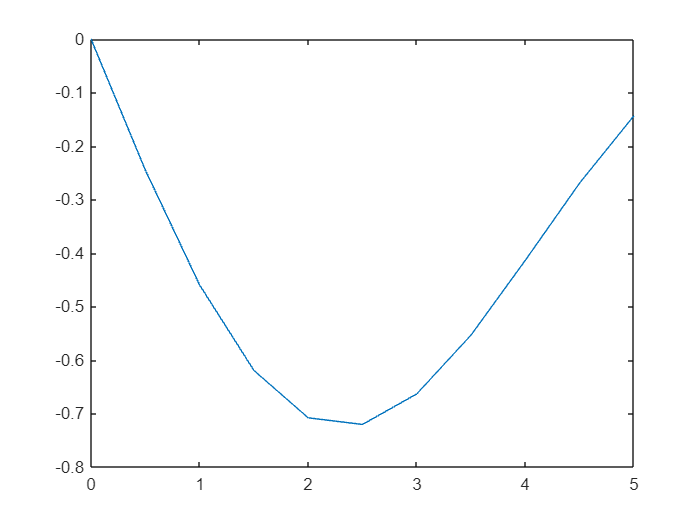

[y2, ki2] = funcos2(x, e);

figure('Name','dV(x)');
plot(x, y2);

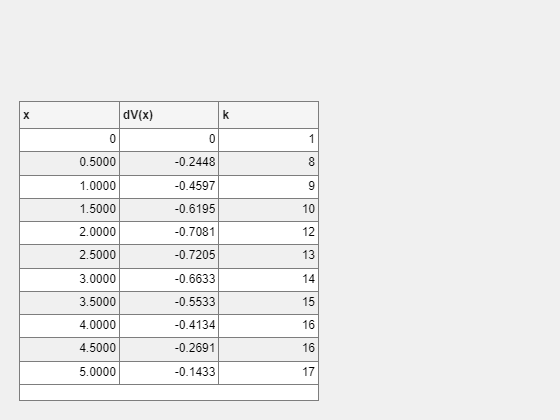

dVxT = table(x',y2',ki2','VariableNames',{'x','dV(x)','k'});
fig = uifigure('Name','dV(x)');
uit = uitable(fig,'Data',dVxT);

Функции:

Интегральный косинус

function [y,ki] = intcos(x,e)
kmax = 100;
y = zeros(size(x));
ki = y;
for i = 1:numel(x)
    a = -x(i)*x(i)/4;
    sum = a;
    k = 1;
    while(abs(a) >= e) && (k < kmax)
        q = -x(i) * x(i) * k / ((k + 1) * (2 * k + 1 ) * (2 * k + 2));
        k = k + 1;
        a = a* q;
        sum = sum + a;
    end
    y(i) = sum;
    ki(i) = k;
end
end

Производная интегрального косинуса:

function [y2,ki2] = funcos2(x,e)
kmax = 100;
y2 = zeros(size(x));
ki2 = y2;
for i = 1:numel(x)
    a = -x(i)/2;
    sum = a;
    k = 1;
    while(abs(a) >= e) && (k < kmax)
        q = -x(i) * x(i)/ ((2 * k + 1 ) * (2 * k + 2));
        k = k + 1;
        a = a * q;
        sum = sum + a;
    end
    y2(i) = sum;
    ki2(i) = k;
end
end

**Вывод**

 Мы изучили способ приближения функции с помощью ряда Тейлора. Таким образом, функцию V(x) и V'(x) можно вычислить с помощью ряда Тейлора на отрезке [0, 5] с шагом 0,5 с заданной точностью. Так же написан код, в котором созданы графики и таблицы.